# Very basic reconstruction of multisclice 2D EPI MRD dataset

## without pre-whitening, ghost correction, GRAPPA or partial Fourier

## Used to explore the MRD dataset, 18/06/2020 Maxime Yon

clearvars; close all; clc;
addpath('/usr/local/share/ismrmrd/matlab')

% define the filename
filename = '/home/valery/Gt_training/FID_ep2d_se_noIPAT_3slices.h5';

% dataset definition
dset = ismrmrd.Dataset(filename, 'dataset');

% Header retrieving
header = ismrmrd.xml.deserialize(dset.readxml);

% Data retrieving
data_struct = dset.readAcquisition();
clearvars dset;

disp('Simple ismrmrd commands allows to retrieve the main Header and the Raw data section of the MRD dataset');

Simple ismrmrd commands allows to retrieve the main Header and the Raw data section of the MRD dataset


% Number of data chunk
N_data_chunk = size(data_struct.data,2);
disp(['The number of data chunk of this acquistion is ' num2str(N_data_chunk)]);

The number of data chunk of this acquistion is 393



% Exploring encoding limits
N_phase_encode = header.encoding.encodingLimits.kspace_encoding_step_1.maximum  + 1;
N_slices = header.encoding.encodingLimits.slice.maximum + 1;

disp('In 2D multisclices EPI we expect these data chunk to come from each phase encode (blips) of each sclices');

In 2D multisclices EPI we expect these data chunk to come from each phase encode (blips) of each sclices


disp('In such case, their number should be the number of kspace_encoding_step_1 * number of slices');

In such case, their number should be the number of kspace_encoding_step_1 * number of slices


disp(['kspace_encoding_step_1 * number of slices = ' num2str(N_phase_encode.*N_slices)]);

kspace_encoding_step_1 * number of slices = 384


disp(['Here there is = ' num2str(N_data_chunk - N_phase_encode.*N_slices) ' additionnal data chunk']);

Here there is = 9 additionnal data chunk


N_3D_encode = header.encoding.encodingLimits.kspace_encoding_step_2.maximum  + 1;
N_average = header.encoding.encodingLimits.average.maximum + 1;
N_repetition = header.encoding.encodingLimits.repetition.maximum + 1;
N_contrast = header.encoding.encodingLimits.contrast.maximum + 1;

disp('We can check that these additional data chunck do not come from 3D Phase encode, Averages, repetitions, contrasts...');

We can check that these additional data chunck do not come from 3D Phase encode, Averages, repetitions, contrasts...


disp('(Unlikely for such a small number of data chunck)');

(Unlikely for such a small number of data chunck)


disp(['3D phase encode =  ' num2str(N_3D_encode) '; Averages =  ' num2str(N_average) '; Repetitions =  ' num2str(N_repetition) '; Contrast =  ' num2str(N_contrast)  ]);

3D phase encode =  1; Averages =  1; Repetitions =  1; Contrast =  1


## use of flags to distinguish calibration data from image data

parallel_calibration = data_struct.head.flagIsSet('ACQ_IS_PARALLEL_CALIBRATION');
navigation_data = data_struct.head.flagIsSet('ACQ_IS_NAVIGATION_DATA');
phase_corr_data = data_struct.head.flagIsSet('ACQ_IS_PHASECORR_DATA');

N_parallel_calibration = sum(parallel_calibration);
N_navigation_data = sum(navigation_data);
N_phase_corr_data = sum(phase_corr_data);

disp('The additional data chunck can also come from parallel calibration, navigation data or phase correction data');

The additional data chunck can also come from parallel calibration, navigation data or phase correction data


disp(['Parallel calibration =  ' num2str(N_parallel_calibration) '; Nagigation data =  ' num2str(N_navigation_data) '; Phase correction data =  ' num2str(N_phase_corr_data)]);

Parallel calibration =  0; Nagigation data =  0; Phase correction data =  9


disp('These Phase correction readout are used for phase correction, here we will simply discard them');

These Phase correction readout are used for phase correction, here we will simply discard them



image_data = find(parallel_calibration+navigation_data+phase_corr_data==0);

## Create matrix of image readout 

readout_size = size(data_struct.data{1,image_data(1,1)},1);
N_coils = size(data_struct.data{1,image_data(1,1)},2);
kspace = zeros(readout_size, N_phase_encode, N_coils,N_slices);

for ind = image_data
    kspace(:,data_struct.head.idx.kspace_encode_step_1(1,ind)+1,:,data_struct.head.idx.slice(1,ind)+1) = data_struct.data{1,ind};
end

disp('We can now create a matrix with the image readout only');

We can now create a matrix with the image readout only


disp(['Its dimensions are: ' num2str(size(kspace))]);

Its dimensions are: 256  128   26    3


disp('Readout points, phase encodes, coils, slices');

Readout points, phase encodes, coils, slices



is_reversed_acq = data_struct.head.flagIsSet('ACQ_IS_REVERSE');
is_reversed_acq = is_reversed_acq(image_data);

disp('In EPI the odd and even echoes are acquired in opposite direction');

In EPI the odd and even echoes are acquired in opposite direction


disp(['This information is available in the flags, showing that half of phase encodes (' num2str(sum(is_reversed_acq)./N_slices) ') are reversed']);

This information is available in the flags, showing that half of phase encodes (64) are reversed



kspace_flip = kspace;
kspace_flip(:,is_reversed_acq+1,:,:) = flip(kspace_flip(:,is_reversed_acq+1,:,:),1);

## direct reconstruction

disp('Simple reconstruction can be perform by 2D FFT');

Simple reconstruction can be perform by 2D FFT



image_noRegrid = FFTKSpace2XSpace(FFTKSpace2XSpace(kspace_flip,1),2);
image_noRegrid = squeeze(sum(abs(image_noRegrid),3));

disp('Siemens usually use oversampling to avoid folding in readout dimension');

Siemens usually use oversampling to avoid folding in readout dimension


disp('This oversampling need to be removed before image display');

This oversampling need to be removed before image display


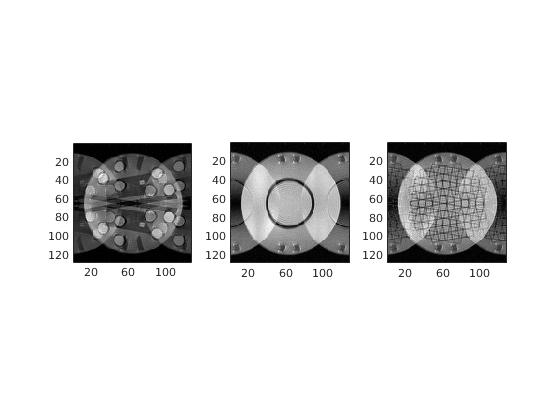

if size(image_noRegrid,1)/header.encoding.encodedSpace.matrixSize.x(1,1)==2
   image_noRegrid = image_noRegrid(round(size(image_noRegrid,1).*0.25)+1:round(size(image_noRegrid,1).*0.75),:,:);
end

figure()
subplot(1,3,1)
imagesc(image_noRegrid(:,:,1));
axis image
subplot(1,3,2)
imagesc(image_noRegrid(:,:,2));
axis image
subplot(1,3,3)
imagesc(image_noRegrid(:,:,3));
axis image
colormap gray

## regridding

disp('The images can be improved by regridding taking into account the ramp time');

The images can be improved by regridding taking into account the ramp time



% retrieve user parameter containing gradient shape parameter
for ind = 1:size(header.encoding.trajectoryDescription.userParameterLong,2)
    parameters.(header.encoding.trajectoryDescription.userParameterLong(1,ind).name) = header.encoding.trajectoryDescription.userParameterLong(1,ind).value;
end
for ind = 1:size(header.encoding.trajectoryDescription.userParameterDouble,2)
    parameters.(header.encoding.trajectoryDescription.userParameterDouble(1,ind).name) = header.encoding.trajectoryDescription.userParameterDouble(1,ind).value;
end
parameters.readout = readout_size;
parameters.N_phase_encode = N_phase_encode;
parameters.N_phase_recon = header.encoding.reconSpace.matrixSize.x(1,1);
parameters.N_slices = N_slices;
parameters.position = data_struct.head.position(:,image_data(1,1));
parameters.read_dir = data_struct.head.read_dir(:,image_data(1,1));
parameters.FOV_1 = header.encoding.encodedSpace.fieldOfView_mm.x(1,1);
parameters.is_reversed_acq = is_reversed_acq;

[kspace_corr] = EPI_trapezoid_regridding(parameters,kspace);

## direct reconstruction after regridding

disp('Simple reconstruction can be perform by FFT');

Simple reconstruction can be perform by 2D FFT


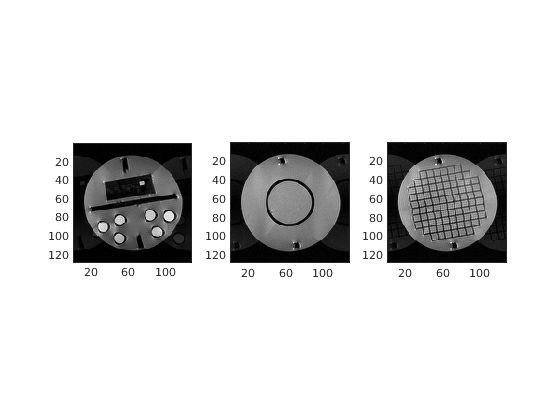


image_Regrid = FFTKSpace2XSpace(kspace_corr,2);
image_Regrid = squeeze(sum(abs(image_Regrid),3));


figure()
subplot(1,3,1)
imagesc(image_Regrid(:,:,1));
axis image
subplot(1,3,2)
imagesc(image_Regrid(:,:,2));
axis image
subplot(1,3,3)
imagesc(image_Regrid(:,:,3));
axis image
colormap gray


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%                  Required functions                         %%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


function [PostFFT] = FFTKSpace2XSpace(PreFFT, Dim)
   
   PostFFT = fftshift(fft(ifftshift(PreFFT, Dim), [], Dim), Dim) ;
   
end